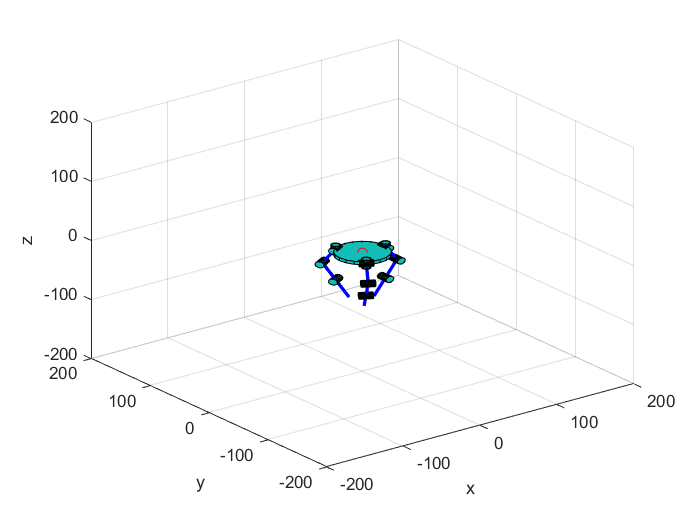

clear all;cla;
global Link_1
global Link_2
global Link_3
Build;
% ROM;
stp=5;
% for i=0:stp:60
%    DHFk_hand([0,i,20,20],[0,i,20,20],[0,i,20,20])
%    drawnow;
% end

q=repmat(1,1,4);
q=[0,60,60,0];
DHFk_hand(q,q,q)

% 定义符号变量
syms theta1 theta2 theta3 theta4 theta5
syms Ctheta1 Ctheta2 Ctheta3 Ctheta4 Ctheta5
syms Stheta1 Stheta2 Stheta3 Stheta4 Stheta5

% ToRad = pi/180;
% theta1=0*ToRad
% theta2=q(1)*ToRad
% theta3=q(2)*ToRad
% theta4=q(3)*ToRad
% theta5=q(4)*ToRad

Ctheta1 = cos(theta1);
Stheta1 = sin(theta1);
Ctheta2 = cos(theta2);
Stheta2 = sin(theta2);
Ctheta3 = cos(theta3);
Stheta3 = sin(theta3);
Ctheta4 = cos(theta4);
Stheta4 = sin(theta4);
Ctheta5 = cos(theta5);
Stheta5 = sin(theta5);
% 定义各个矩阵
T01 = [1, 0, 0, 0;
       0, 1, 0, 0;
       0, 0, 1, 0;
       0, 0, 0, 1];

T12 = [Ctheta1, Stheta1, 0, 30*Ctheta1;
       Stheta1, -Ctheta1, 0, 30*Stheta1;
       0, 0, -1, 0;
       0, 0, 0, 1];

T23 = [Ctheta2, 0, Stheta2, 0;
       Stheta2, 0, -Ctheta2, 0;
       0, 1, 0, 0;
       0, 0, 0, 1];

T34 = [Ctheta3, -Stheta3, 0, 30*Ctheta3;
       Stheta3, Ctheta3, 0, 30*Stheta3;
       0, 0, 1, 0;
       0, 0, 0, 1];

T45 = [Ctheta4, -Stheta4, 0, 30*Ctheta4;
       Stheta4, Ctheta4, 0, 30*Stheta4;
       0, 0, 1, 0;
       0, 0, 0, 1];

T5end = [Ctheta5, -Stheta5, 0, 30*Ctheta5;
         Stheta5, Ctheta5, 0, 30*Stheta5;
         0, 0, 1, 0;
         0, 0, 0, 1];

% 矩阵乘积计算
T0end = T01 * T12 * T23 * T34 * T45 * T5end;
% 展示结果
disp('^0T_{end} = ');

^0T_{end} = 


disp(T0end);


% 对每个元素分别对theta1求偏导
T0end_dtheta1 = diff(T0end, theta1);

% 展示对theta1的偏导结果
disp('偏导数对theta1: ');

偏导数对theta1: 


disp(T0end_dtheta1);


% 对每个元素分别对theta2求偏导
T0end_dtheta2 = diff(T0end, theta2);

% 展示对theta2的偏导结果
disp('偏导数对theta2: ');

偏导数对theta2: 


disp(T0end_dtheta2);


% 对每个元素分别对theta3求偏导
T0end_dtheta3 = diff(T0end, theta3);

% 展示对theta3的偏导结果
disp('偏导数对theta3: ');

偏导数对theta3: 


disp(T0end_dtheta3);


% 对每个元素分别对theta4求偏导
T0end_dtheta4 = diff(T0end, theta4);

% 展示对theta4的偏导结果
disp('偏导数对theta4: ');

偏导数对theta4: 


disp(T0end_dtheta4);


% 对每个元素分别对theta5求偏导
T0end_dtheta5 = diff(T0end, theta5);

% 展示对theta5的偏导结果
disp('偏导数对theta5: ');

偏导数对theta5: 


disp(T0end_dtheta5);

$$\begin{array}{l} \left(\begin{array}{cccc} -\cos\left(\theta_{5}\right)\,\sigma_{6}-\sin\left(\theta_{5}\right)\,\sigma_{4} & \sin\left(\theta_{5}\right)\,\sigma_{6}-\cos\left(\theta_{5}\right)\,\sigma_{4} & 0 & -30\,\cos\left(\theta_{5}\right)\,\sigma_{6}-30\,\sin\left(\theta_{5}\right)\,\sigma_{4}\\ \cos\left(\theta_{5}\right)\,\sigma_{5}+\sin\left(\theta_{5}\right)\,\sigma_{3} & \cos\left(\theta_{5}\right)\,\sigma_{3}-\sin\left(\theta_{5}\right)\,\sigma_{5} & 0 & 30\,\cos\left(\theta_{5}\right)\,\sigma_{5}+30\,\sin\left(\theta_{5}\right)\,\sigma_{3}\\ \sin\left(\theta_{5}\right)\,\sigma_{2}-\cos\left(\theta_{5}\right)\,\sigma_{1} & \cos\left(\theta_{5}\right)\,\sigma_{2}+\sin\left(\theta_{5}\right)\,\sigma_{1} & 0 & 30\,\sin\left(\theta_{5}\right)\,\sigma_{2}-30\,\cos\left(\theta_{5}\right)\,\sigma_{1}\\ 0 & 0 & 0 & 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(\theta_{3}\right)\,\cos\left(\theta_{4}\right)-\sin\left(\theta_{3}\right)\,\sin\left(\theta_{4}\right)\\ \sigma_{2}=\cos\left(\theta_{3}\right)\,\sin\left(\theta_{4}\right)+\cos\left(\theta_{4}\right)\,\sin\left(\theta_{3}\right)\\ \sigma_{3}=\cos\left(\theta_{3}\right)\,\cos\left(\theta_{4}\right)\,\sigma_{7}-\sin\left(\theta_{3}\right)\,\sin\left(\theta_{4}\right)\,\sigma_{7}\\ \sigma_{4}=\cos\left(\theta_{3}\right)\,\cos\left(\theta_{4}\right)\,\sigma_{8}-\sin\left(\theta_{3}\right)\,\sin\left(\theta_{4}\right)\,\sigma_{8}\\ \sigma_{5}=\cos\left(\theta_{3}\right)\,\sin\left(\theta_{4}\right)\,\sigma_{7}+\cos\left(\theta_{4}\right)\,\sin\left(\theta_{3}\right)\,\sigma_{7}\\ \sigma_{6}=\cos\left(\theta_{3}\right)\,\sin\left(\theta_{4}\right)\,\sigma_{8}+\cos\left(\theta_{4}\right)\,\sin\left(\theta_{3}\right)\,\sigma_{8}\\ \sigma_{7}=\cos\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right)-\cos\left(\theta_{2}\right)\,\sin\left(\theta_{1}\right)\\ \sigma_{8}=\cos\left(\theta_{1}\right)\,\cos\left(\theta_{2}\right)+\sin\left(\theta_{1}\right)\,\sin\left(\theta_{2}\right) \end{array}$$


% 获取每个偏导矩阵的第四列前三行
dtheta1_col4 = T0end_dtheta1(1:3, 4);
dtheta2_col4 = T0end_dtheta2(1:3, 4);
dtheta3_col4 = T0end_dtheta3(1:3, 4);
dtheta4_col4 = T0end_dtheta4(1:3, 4);
dtheta5_col4 = T0end_dtheta5(1:3, 4);
jv_matrix = [dtheta1_col4, dtheta2_col4, dtheta3_col4, dtheta4_col4, dtheta5_col4];
disp('jv_matrix:');

jv_matrix:


disp(jv_matrix);


T12_col3 = T12(1:3, 3);
T23_col3 = T23(1:3, 3);
T34_col3 = T34(1:3, 3);
T45_col3 = T45(1:3, 3);
T5end_col3 = T5end(1:3, 3);
jw_matrix = [T12_col3, T23_col3, T34_col3, T45_col3, T5end_col3];
disp('jw_matrix:');

jw_matrix:


disp(jw_matrix);

$$\left(\begin{array}{ccccc} 0 & \sin\left(\theta_{2}\right) & 0 & 0 & 0\\ 0 & -\cos\left(\theta_{2}\right) & 0 & 0 & 0\\ -1 & 0 & 1 & 1 & 1 \end{array}\right)$$


j_matrix = [jv_matrix; jw_matrix]; 
disp('雅可比矩阵:');

雅可比矩阵:


disp(j_matrix);

% save('j_matrix.mat', 'j_matrix');
q=[0,0,60,60,0];
Jacobian_finger(q)

错误使用 symengine
Unable to convert expression containing symbolic variables into double array. Apply 'subs' function first to substitute values for variables.

出错 sym/double (第 800 行)
        Xstr = mupadmex('symobj::double', S.s, 0);

出错 Jacobian_finger (第 14 行)
    J = double(J);